# Trabalho de EE-254 (Controle Preditivo): Parte 2

**Observação:** Este trabalho deve ser realizado **sem o uso do MPT Toolbox.**

Considere o seguinte sistema de dois carros acoplados por uma mola:

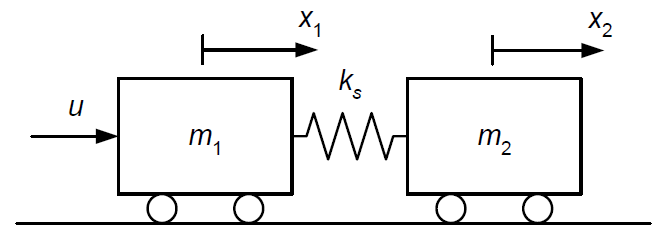

com deslocamentos $x_1$, $x_2$ definidos de modo que a mola esteja relaxada quando $x_1 = x_2$.  

A dinâmica deste sistema, a tempo contínuo, é descrita pelas seguintes equações:


$$m_1 \ddot{x}_1(t) = u(t) + k_s \big[\, x_2(t) - x_1(t) \,\big] $$



$$m_2 \ddot{x}_2(t) = - k_s \big[\, x_2(t) - x_1(t) \,\big]$$


que podem ser colocadas na forma 


$$\dot{x}(t) = A_c x(t) + B_c u(t) $$


com $x_3 = \dot{x}_1$, $x_4 = \dot{x}_2$ e

$A_c =
\left[
  \begin{array}{cccc}
    0 & 0 & 1 & 0 \\[4pt]
    0 & 0 & 0 & 1 \\[4pt]
    -k_s/m_1 & k_s/m_1 & 0 & 0 \\[4pt]
    k_s/m_2 & -k_s/m_2 & 0 & 0 \\
  \end{array}
\right]$, $B_c =
\left[
  \begin{array}{c}
    0 \\[4pt]
    0 \\[4pt]
    1/m_1 \\[4pt]
    0 \\
  \end{array}
\right]$

Neste trabalho, serão adotados os seguintes valores para os parâmetros do modelo:

$m_1 = 5$ kg, $m_2 = 3$ kg, $k_s = 10$ N/m, $g = 9\text{,}8$ m/s${}^2$

que resultam nas matrizes $A_c$, $B_c$ definidas no código abaixo:

clear, clc, close all
m1 = 5; m2 = 3; ks = 10; g = 9.8;
Ac = [0 0 1 0;
      0 0 0 1;
      -ks/m1 ks/m1 0 0;
      ks/m2 -ks/m2 0 0];
Bc = [0;0;1/m1;0];

Deseja-se conduzir o estado do sistema para a origem, partindo da seguinte condição inicial:


$$x(0) = \left[
\begin{array}{c}
-1 \text{ m}\\
-1 \text{ m}\\
0 \\
0 \\
\end{array}
\right]$$


Adicionalmente, deseja-se que a deformação da mola e o controle (ambos em módulo) não ultrapassem 0,05 m e 2 N, respectivamente.

O código abaixo obtém as matrizes $A$ e $B$ da equação de estado discretizada:


$$x(k+1) = A x(k) + B u(k)$$


considerando que o controle seja aplicado por meio de um segurador de ordem zero com período de amostragem $T = 0\text{,}2$ s.

T = 0.2;
[A,B] = c2dm(Ac,Bc,[],[],T,'zoh');

**Item a (4,0 pontos)** Considere um controlador DLQR com ganho $K$obtido da seguinte forma: 

q1 = 10; q2 = 10; q3 = 1; q4 = 1; q5 = 100;
Q = [q1 + q5 -q5 0 0; -q5 q2 + q5 0 0; 0 0 q3 0; 0 0 0 q4];
R = 1;
[K,P] = dlqr(A,B,Q,R);

lembrando que a matriz $P$ é a solução positivo-definida da equação algébrica de Riccati.

Empregando a função `determina_oinf.m` disponibilizada, obtenha o conjunto $\mathcal{O}_\infty = \{x : S_f x \leq b_f \}$ associado à dinâmica de malha fechada considerando as restrições de controle e estado impostas para a operação do sistema.

% Sf x < bf
Gamma = eye(4) ;
max_iter = 100 ;

b1 = 0.05

b1 = 0.0500

b2 = 2 

b2 = 2


Af = A - B*K

Af =     0.9381    0.0472    0.1631    0.0039
    0.0652    0.9346    0.0040    0.1956
   -0.6106    0.4647    0.6207    0.0513
    0.6382   -0.6415    0.0579    0.9348



% Deformação da mola: -0.05 <= x1 - x2 <= 0.05
Sx = [1 -1 0 0;-1 1 0 0];
bx = [0.05;0.05];

% Controle: -2 <= u <= 2
Su = [1;-1];
bu = [2;2];

Gamma = [eye(4);-K];
Spsi = [Sx zeros(2,1); zeros(2,4) Su]

Spsi =      1    -1     0     0     0
    -1     1     0     0     0
     0     0     0     0     1
     0     0     0     0    -1


bpsi = [bx;bu];

[Sf_1, bf_1, Si_1, bi_1] = determina_oinf(Af, Gamma, Spsi, bpsi, max_iter);

Iteração 1 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 2 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 3 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 4 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 5 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 6 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 7 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 8 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 9 / 100

Optimal soluti



%{
bpsi = bx;
Spsi = Sx;
[Sf_0, bf_0, Si_0, bi_0] = determina_oinf(Af, Gamma, Spsi, bpsi, max_iter)
%Su = [1 0 0 0;-1 0 0 0];
%Spsi = [Sx;Su]
%Spsi = [Sx zeros(2,1);zeros(2,1) Su]

Su = [1 0 0 0;-1 0 0 0];
bu = [b2;b2];
bpsi = bu;
Spsi = Su;
[Sf_2, bf_2, Si_2, bi_2] = determina_oinf(Af, Gamma, Spsi, bpsi, max_iter)
%}


**Observação:** Caso não tenha sido possível completar este item, carregue o arquivo `oinf.mat` disponibilizado.

#### Item b (2,0 pontos)

Elabore um código para mostrar que $x(0) \neq \mathcal{O}_\infty$.

**Dica:** Basta mostrar que nem todas as linhas da desigualdade $S_f x(0) \leq b_f$ são satisfeitas.

x0 = [-1;-1;0;0]; % Condição inicial

max_iter = 100 ;

b1 = 0.05

b1 = 0.0500

b2 = 2 

b2 = 2


x1 = [-b1; -b1; b1; b1] 

x1 =    -0.0500
   -0.0500
    0.0500
    0.0500


x2 = [-b2; b2; b2; b2]

x2 =     -2
     2
     2
     2



file = load('oinf.mat');
Sf = file.Sf;
bf = file.bf;

m = Sf * x0

m =          0
         0
    3.6955
   -3.6955
    0.0145
   -0.0145
    2.3568
   -2.3568
    0.0498
   -0.0498


[rows, columns] = size(m)

rows = 48

columns = 1


%{
verificar se o resultado da multiplicacao de matrizes respeita as restrições
[s11 s12][x1*] <= [b1]
[s21 s22][x2*] <= [b2]

s11*x1+s12*x2<= b1
e
s21*x1+s22*x2<= b2
com
x1=x1* e x2=x2*
%}   

 fprintf('element >= %d', bf)

element >= 5.000000e-02element >= 5.000000e-02element >= 2element >= 2element >= 5.000000e-02element >= 5.000000e-02element >= 2element >= 2element >= 5.000000e-02element >= 5.000000e-02element >= 2element >= 2element >= 5.000000e-02element >= 5.000000e-02element >= 2element >= 2element >= 5.000000e-02element >= 5.000000e-02element >= 2element >= 2element >= 5.000000e-02element >= 5.000000e-02element >= 2element >= 2element >= 5.000000e-02element >= 5.000000e-02element >= 2element >= 2element >= 5.000000e-02element >= 5.000000e-02element >= 2element >= 2element >= 5.000000e-02element >= 5.000000e-02element >= 5.000000e-02element >= 5.000000e-02element >= 5.000000e-02element >= 5.000000e-02element >= 5.000000e-02element >= 5.000000e-02element >= 5.000000e-02element >= 5.000000e-02element >= 5.000000e-02element >= 5.000000e-02element >= 5.000000e-02element >= 5.000000e-02element >= 5.000000e-02element >= 5.000000e-02


for i = 1:rows
    for j = 1:columns
        
        element = m(i,j);
        if element > bf(i,j)
           fprintf('element %d, %d = %d  > %d  \n ', i, j, element, bf(i,j))
        end

    end
end

element 3, 1 = 3.695462e+00  > 2  
 element 7, 1 = 2.356846e+00  > 2  
 element 13, 1 = 8.956318e-02  > 5.000000e-02  
 element 17, 1 = 1.199852e-01  > 5.000000e-02  
 element 21, 1 = 1.319490e-01  > 5.000000e-02  
 element 25, 1 = 1.222123e-01  > 5.000000e-02  
 element 29, 1 = 9.307835e-02  > 5.000000e-02  
 element 33, 1 = 5.099036e-02  > 5.000000e-02  
 element 40, 1 = 6.948348e-02  > 5.000000e-02  
 element 42, 1 = 8.656400e-02  > 5.000000e-02  
 element 44, 1 = 8.869863e-02  > 5.000000e-02  
 element 46, 1 = 7.835317e-02  > 5.000000e-02  
 element 48, 1 = 5.995678e-02  > 5.000000e-02  
 


%{

m = Sf * x2
[rows, columns] = size(m)
 fprintf('element >= %d', b2)

for i = 1:rows
    for j = 1:columns
        
        element = m(i,j);
        if norm(element) > b2
           fprintf('element %d, %d = %d \n ', i, j, element)
        end

    end
end
%}   



#### Item c (4,0 pontos)

Complete o código abaixo para simular o sistema em malha fechada empregando a lei de controle preditivo apresentada na Aula 8. Para isso, sugere-se empregar a função dlqrcon`.m` disponibilizada.

N = 15; % Horizonte de controle a ser adotado
x0 = [-1;-1;0;0]; % Condição inicial
x{1} = x0;
sys = ss(Ac,Bc,[],[]);
trec = 0; xrec = x{1}'; 

Su = [1; -1];
bu = [2; 2];

xbar = zeros(4,1); ubar = 0;
nt = 10; kf = 100; warning off
t = 0:nt:kf; % Vetor de tempo
u = zeros(1, kf); % 1 sinal de controle, cada coluna representa um tempo
y = zeros(1, kf); 
x = zeros(4, kf); % 4 estados, cada coluna representa um tempo
k=1;
x(:,k) = x0;

xbar = zeros(4,1); ubar = 0;
nt = 10; kf = 100;
vector_t = 0:1:kf-1; % Vetor de tempo
k=1;
x(:,k) = x0;

% considerando eq de saída da forma y(t)=x(t)
C = [0 1 0 0];


for k = 1:kf-1  
    %aula 8 slide 60
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % obter u{k} com base em x{k} %
    %u(k) = ubar - K*(x(:,k)  - xbar) 
    un = dlqrcon(A,B,Q,R,P,N,Sx,bx,Su,bu,Sf,bf,x(:,k),xbar,ubar);
    u(k) = un(1);

    x(:,k+1) = A*x(:,k)  + B*u(k);
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    t = linspace((k-1)*T,k*T,nt);

    U = repmat(u(k)',nt,1);
    [~,tout,xout] = lsim(sys,U,t,x(:,k));
    trec = [trec;tout(2:end)];
    xrec = [xrec;xout(2:end,:)];
    x(:, k+1) = xrec(end,:)';
    
    y(k) = C * x(:, k);
end

ans =     60     4


ans =     76     1


ans =     76    60


ans =     30     1


ans =     76     1


ans =     76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans =     60     4


ans =     76     1


ans =     76    60


ans =     30     1


ans =     76     1


ans =     76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans =     60     4


ans =     76     1


ans =     76    60


ans =     30     1


ans =     76     1


ans =     76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans =     60     4


ans =     76     1


ans =     76    60


ans =     30     1


ans =     76     1


ans =     76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans =     60     4


ans =     76     1


ans =     76    60


ans =     30     1


ans =     76     1


ans =     76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans =     60     4


ans =     76     1


ans =     76    60


ans =     30     1


ans =     76     1


ans =     76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans =     60     4


ans =     76     1


ans =     76    60


ans =     30     1


ans =     76     1


ans =     76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans =     60     4


ans =     76     1


ans =     76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ans = 1×2
    60     4


ans = 1×2
    76     1


ans = 1×2
    76    60


ans = 1×2
    30     1


ans = 1×2
    76     1


ans = 1×2
    76     1



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


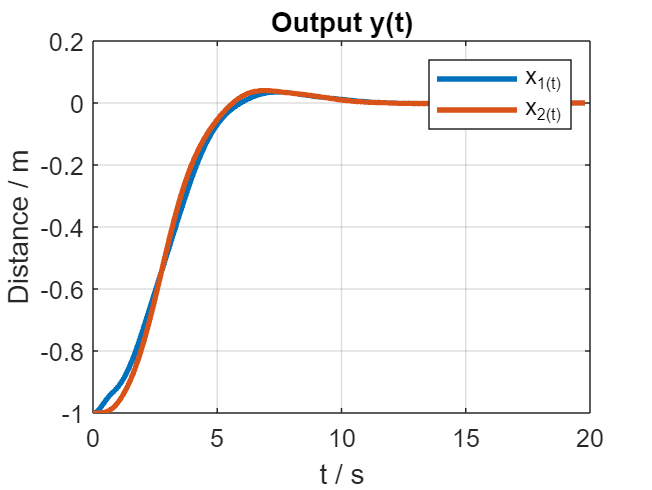



S = stepinfo(y,vector_t,1,0,'RiseTimeLimits',[0.1,0.9]);
RiseTime = S.RiseTime;

% Gráfico dos deslocamentos
figure
yrec = xrec(:,2);
h = plot(trec,xrec(:,1), trec,xrec(:,2)); 
set(h,'LineWidth',2), grid
hold on
xline(RiseTime,'--black');
text(RiseTime,0,['Rise time: ',num2str(round(RiseTime,2)),' s'],'HorizontalAlignment','right','VerticalAlignment','bottom');
xlabel('t / s'), ylabel('Distance / m')
title('Output y(t)');
legend('x_1(t)', 'x_2(t)')

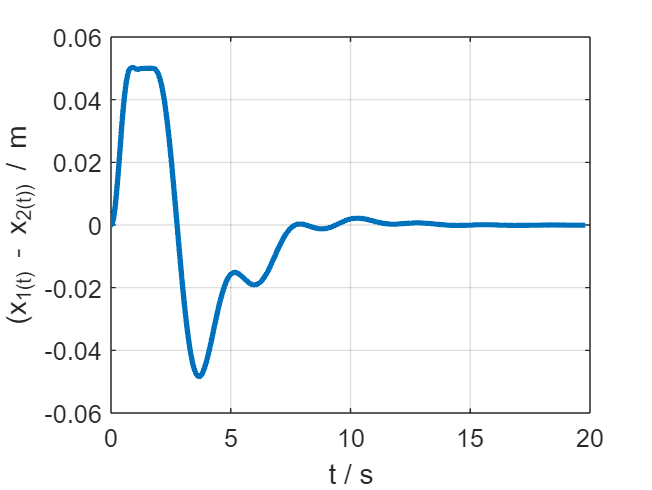



% Gráfico da deformação da mola
figure
h = plot(trec,xrec(:,1)-xrec(:,2));
set(h,'LineWidth',2), grid
xlabel('t / s'), ylabel('(x_1(t) - x_2(t)) / m')



% Gráfico do controle
figure
a=[0:kf]*T

a = 1×101
         0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000


b=[u u(end)]

b = 1×101
    2.0000    1.1920   -0.2466   -0.0793    1.0932    1.5207    1.2405    1.3734    1.2659    0.8513    0.5638    0.3615    0.2036    0.0581   -0.0943   -0.2591   -0.4303   -0.5943   -0.7347   -0.8375   -0.8937   -0.9017   -0.8669   -0.7999   -0.7144   -0.6240   -0.5402   -0.4703   -0.4173   -0.3801


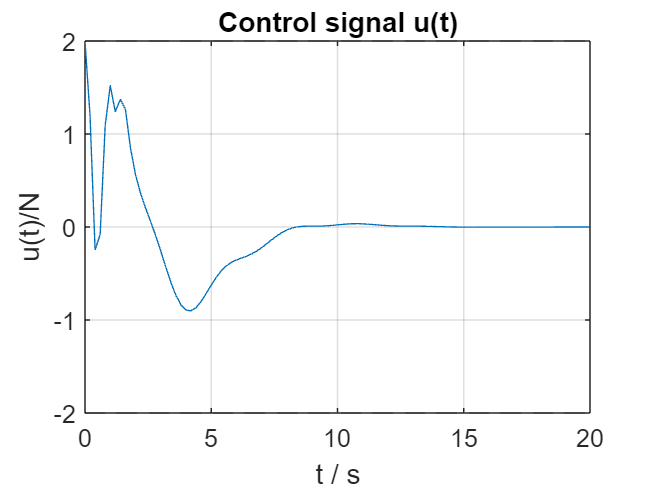

plot(a, b); hold on;
yline(2,'--black');
yline(-2,'--black');
title('Control signal u(t)');
ylabel('u(t)/N');
xlabel('t / s');
grid on;


%{

% u(k) = un(1);
un = dlqrcon(A,B,Q,R,P,N,Sx,bx,Su,bu,Sf,bf,x0,xbar,ubar)

while (max(Sf*x(:,k) - bf) > 0)
    un = dlqrcon(A,B,Q,R,P,N,Sx,bx,Su,bu,Sf,bf,x(:,k),xbar,ubar);
    u(k) = un(1);
    x(:, k+1)  = A*x(:,k) + B*u(k);
    k=k+1;
end


h = stairs([0:kf]*T,[cell2mat(u) u{end}]);
set(h,'LineWidth',2)
xlabel('t / s'), ylabel('u(t) / N')
title('Spring deformation: x1(t) - x2(t)');
%}   